clear

load('ampa.mat')
voltage_normmeana=voltage_normmean;
load('nmda.mat')



clf
n=floor(length(voltage_normf)/10000)+1

n = 11

for i=1:n
    
    if i<n
subplot(n,1,i)

plot(Vtimes2((i-1)*10000+1:i*10000),voltage_normmeana((i-1)*10000+1:i*10000))
hold on 
plot(Vtimes2((i-1)*10000+1:i*10000),voltage_normmean((i-1)*10000+1:i*10000))
     else
      subplot(n,1,i)
       plot(Vtimes2((i-1)*10000+1:length(Vtimes2)),voltage_normmeana((i-1)*10000+1:length(voltage_normmean)))   
        plot(Vtimes2((i-1)*10000+1:length(Vtimes2)),voltage_normmean((i-1)*10000+1:length(voltage_normmean)))   
    end
end

clear s
for i=1:n
    if i<n
    s{i}=voltage_normmeana((i-1)*10000+1:i*10000);
    else
    s{i}=voltage_normmeana((i-1)*10000+1:length(voltage_normmean));
    end
end
leap=length(s{n});
s{n}(leap+1:10000)=0;
s=cell2mat(s);

%s_norm = s;
for i = 1:n
    base=mean(s(1:950,i));
    s_norm(:,i) = s(:,i)-base;
end

clear sb
for i=1:n
    if i<n
    sb{i}=voltage_normmean((i-1)*10000+1:i*10000);
    else
    sb{i}=voltage_normmean((i-1)*10000+1:length(voltage_normmean));
    end
end
leap=length(sb{n});
sb{n}(leap+1:10000)=0;
sb=cell2mat(sb);

%sb_norm = sb;
for i = 1:n
    base=mean(sb(500:950,i)); %%%
    sb_norm(:,i) = sb(:,i)-base;
end


clf
n=floor(length(voltage_normf)/10000)+1

n = 11

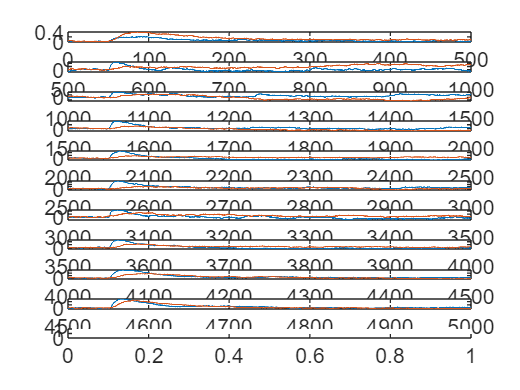

for i=1:n
    
    if i<n
subplot(n,1,i)

plot(Vtimes2((i-1)*10000+1:i*10000),s_norm((i-1)*10000+1:i*10000))
hold on 
plot(Vtimes2((i-1)*10000+1:i*10000),sb_norm((i-1)*10000+1:i*10000))
     else
      subplot(n,1,i)
       plot(Vtimes2((i-1)*10000+1:length(Vtimes2)),s_norm((i-1)*10000+1:length(voltage_normmean))) 
       hold on
        plot(Vtimes2((i-1)*10000+1:length(Vtimes2)),sb_norm((i-1)*10000+1:length(voltage_normmean)))   
    end
end


% clf
% 
% n=floor(length(voltage_normf)/10000)+1
% for i=1:n
%     
%     if i<n
% subplot(n,1,i)
% 
% plot(Vtimes2((i-1)*10000+1:i*10000),s((i-1)*10000+1:i*10000))
% hold on 
% plot(Vtimes2((i-1)*10000+1:i*10000),sb((i-1)*10000+1:i*10000))
%      else
%       subplot(n,1,i)
%        plot(Vtimes2((i-1)*10000+1:length(Vtimes2)),s((i-1)*10000+1:length(voltage_normmean))) 
%        hold on
%         plot(Vtimes2((i-1)*10000+1:length(Vtimes2)),sb((i-1)*10000+1:length(voltage_normmean)))   
%     end
% end


for i=1:n
    ampa(i)= max(s_norm(1000:2000,i)); %max(s_norm(1:1000,i));
    nmda(i)= max(sb_norm(1000:2000,i)); %max(sb_norm(1:1000,i));
end

bad = find(ampa < 0.1)

bad = 11

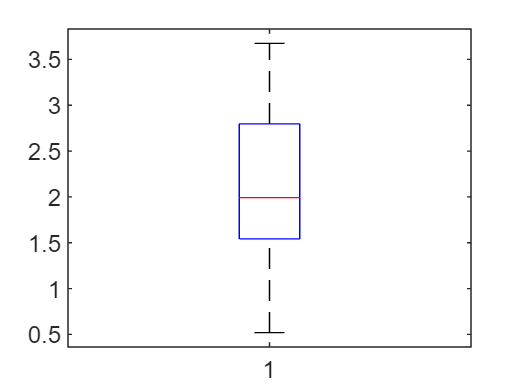


ampa(bad) = [];
nmda(bad) = [];

sb_norm(:,bad) = [];
s_norm(:,bad) = [];


ratio=ampa./nmda;
figure, boxplot(ratio)


n = size(sb_norm,2)

n = 10

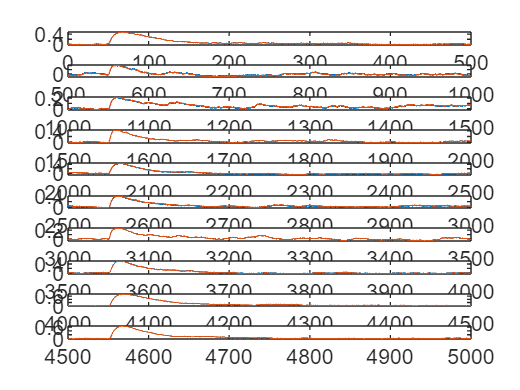

for i=1:size(sb_norm,2)

    subplot(n,1,i)
    
    plot(Vtimes2((i-1)*10000+1:i*10000),s_norm((i-1)*10000+1:i*10000))
    hold on 
    plot(Vtimes2((i-1)*10000+1:i*10000),sb_norm((i-1)*10000+1:i*10000))

end

% figure, hold on
% %for i = 1:24
% %clf
% 
% i = 17;
% sm=smooth(Vtimes2((i-1)*10000+1:i*10000),s_norm((i-1)*10000+1:i*10000),30);
% sbm=smooth(Vtimes2((i-1)*10000+1:i*10000),sb_norm((i-1)*10000+1:i*10000),30);
% 
% plot(Vtimes2((i-1)*10000+1:i*10000),sm)
% plot(Vtimes2((i-1)*10000+1:i*10000),sbm)  
% %pause
% %end  

% figure
% %i=3
% i = 25
% sm=smooth(Vtimes2((i-1)*10000-1000:i*10000),s_norm((i-1)*10000-1000:i*10000),200);
% sbm=smooth(Vtimes2((i-1)*10000-1000:i*10000),sb_norm((i-1)*10000-1000:i*10000),200);
% 
% plot(Vtimes2((i-1)*10000-1000:i*10000),sm)
% hold on 
% plot(Vtimes2((i-1)*10000-1000:i*10000),sbm)





figure
i = 1

i = 1

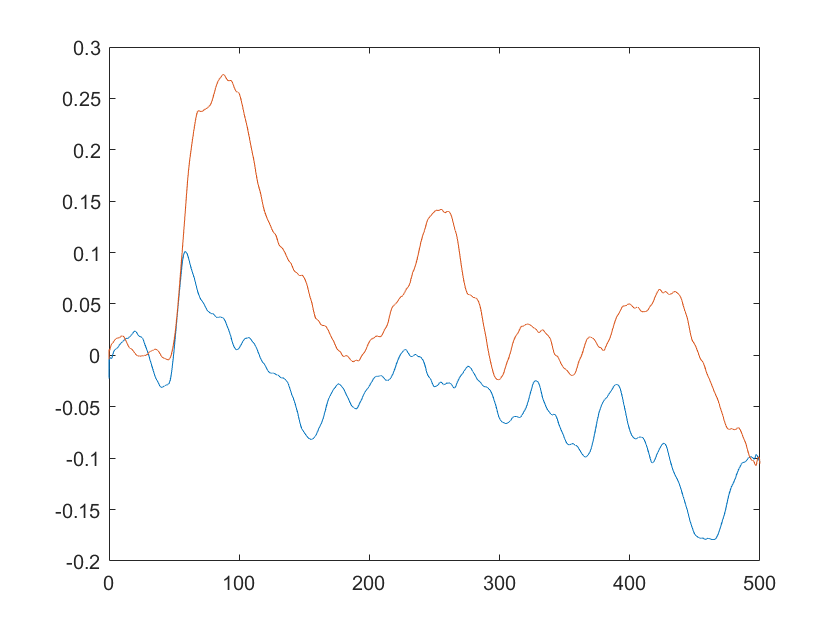

sm=smooth(Vtimes2((i-1)*10000+1:i*10000),s_norm((i-1)*10000+1:i*10000),200);
sbm=smooth(Vtimes2((i-1)*10000+1:i*10000),sb_norm((i-1)*10000+1:i*10000),200);

plot(Vtimes2((i-1)*10000+1:i*10000),sm)
hold on 
plot(Vtimes2((i-1)*10000+1:i*10000),sbm)


save('branch2(2).mat')%,'ampa','nmda','ratio')

% save('oblique.mat','ampa','nmda','ratio')


P21ratio_basal = [ratio06161 ratio06181 ratio07142 ratio07162];
P21ratio_oblique = [ratio06162 ratio06182 ratio06191 ratio06192 ratio07143];

x = [P21ratio_basal P21ratio_oblique];
g = [ones(size(P21ratio_basal)), 2*ones(size(P21ratio_oblique))];
figure, boxplot(x,g)
hold on
xx=repmat(1,length(P21ratio_basal),1);
scatter(xx(:),P21ratio_basal(:),'filled','MarkerFaceAlpha',0.6','jitter','on','jitterAmount',0.13);
xx=repmat(2,length(P21ratio_oblique),1);
scatter(xx(:),P21ratio_oblique(:),'filled','MarkerFaceAlpha',0.6','jitter','on','jitterAmount',0.13);

ad_ratio_basal = [ratio06281 ratio06292 ratio07202 ratio07302 ];
ad_ratio_oblique = [ratio06282 ratio06291 ratio07201 ratio07212 ratio07303];
%%
x = [ad_ratio_basal ad_ratio_oblique];
g = [ones(size(ad_ratio_basal)), 2*ones(size(ad_ratio_oblique))];
figure, boxplot(x,g)
hold on
xx=repmat(1,length(ad_ratio_basal),1);
scatter(xx(:),ad_ratio_basal(:),'filled','MarkerFaceAlpha',0.6','jitter','on','jitterAmount',0.13);
xx=repmat(2,length(ad_ratio_oblique),1);
scatter(xx(:),ad_ratio_oblique(:),'filled','MarkerFaceAlpha',0.6','jitter','on','jitterAmount',0.13);

x = [P21ratio_basal P21ratio_oblique ad_ratio_basal ad_ratio_oblique];
g = [ones(size(P21ratio_basal)), 2*ones(size(P21ratio_oblique)), 3*ones(size(ad_ratio_basal)), 4*ones(size(ad_ratio_oblique))];
figure, boxplot(x,g)
hold on
xx=repmat(1,length(P21ratio_basal),1);
scatter(xx(:),P21ratio_basal(:),'filled','MarkerFaceAlpha',0.6','jitter','on','jitterAmount',0.2);
xx=repmat(2,length(P21ratio_oblique),1);
scatter(xx(:),P21ratio_oblique(:),'filled','MarkerFaceAlpha',0.6','jitter','on','jitterAmount',0.2);
xx=repmat(3,length(ad_ratio_basal),1);
scatter(xx(:),ad_ratio_basal(:),'filled','MarkerFaceAlpha',0.6','jitter','on','jitterAmount',0.2);
xx=repmat(4,length(ad_ratio_oblique),1);
scatter(xx(:),ad_ratio_oblique(:),'filled','MarkerFaceAlpha',0.6','jitter','on','jitterAmount',0.2);


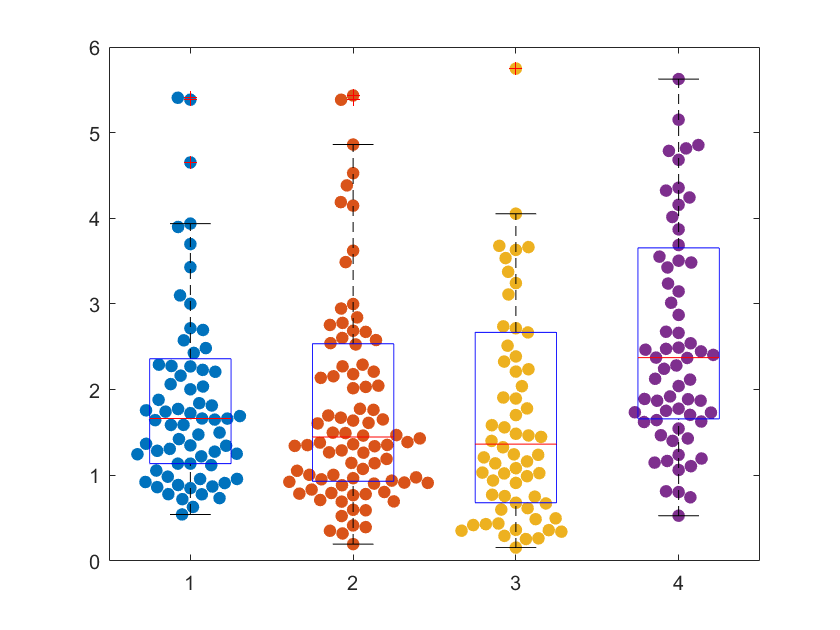

x = [P21ratio_basal P21ratio_oblique ad_ratio_basal ad_ratio_oblique]';
g = [ones(size(P21ratio_basal)) 2*ones(size(P21ratio_oblique)) 3*ones(size(ad_ratio_basal)) 4*ones(size(ad_ratio_oblique))]';
clf
figure, 
ylim([0 6])
xlim([0.5 4.5])
beeswarm(g,x,'sort_style','rand','dot_size',1.1,'MarkerFaceAlpha',1,'use_current_axes',true);
hold on,
boxplot(x,g)
ylim([0 6])
xlim([0.5 4.5])

%adult
ampa_b = [ampa_6281 ampa_6292 ampa_7202 ampa_7302 ];
ampa_o = [ampa_6282 ampa_6291 ampa_7201 ampa_7212 ampa_7303];

nmda_b = [nmda_6281 nmda_6292 nmda_7202 nmda_7302 ];
nmda_o = [nmda_6282 nmda_6291 nmda_7201 nmda_7212 nmda_7303];

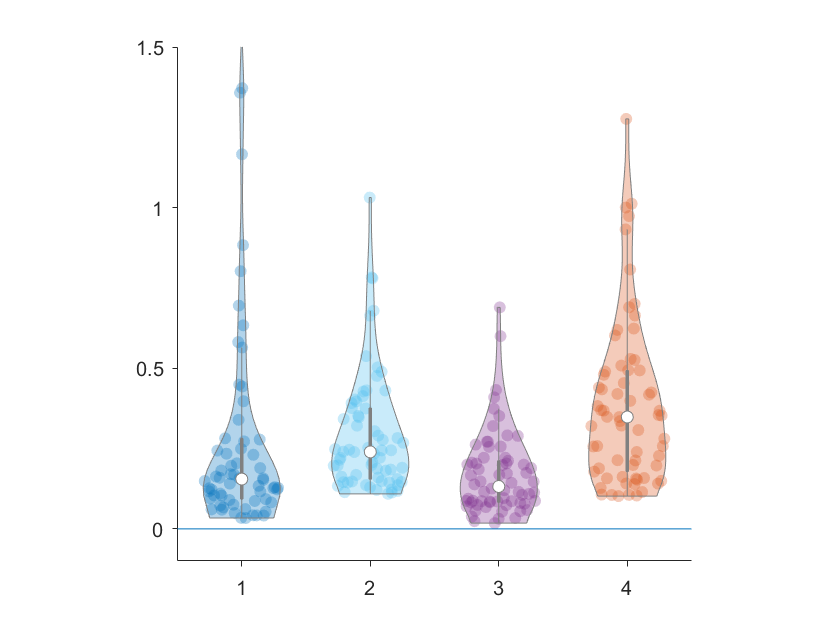


x = [nmda_b ampa_b nmda_o ampa_o]';
g = [ones(size(nmda_b)) 2*ones(size(ampa_b)) 3*ones(size(nmda_o)) 4*ones(size(ampa_o))]';

figure, violinplot(x, g,'bandwidth',.1);
ylim([-0.1 1.5])
xlim([0.5 4.5])
set(gca,'TickDir','out'), box off
axis square

line([0.5 4.5],[0,0])

% clf
% figure, 
% ylim([0 0.5])
% xlim([0.5 4.5])
% beeswarm(g,x,'sort_style','rand','dot_size',1.1,'MarkerFaceAlpha',1,'use_current_axes',true);
% hold on,
% boxplot(x,g)
% ylim([-0.1 1.5])
% xlim([0.5 4.5])



%p21
P21ampa_b = [ampa_6161 ampa_6181 ampa_7142 ampa_7162];
P21ampa_o = [ampa_6162 ampa_6182 ampa_6191 ampa_6192 ampa_7143];

P21nmda_b = [nmda_6161 nmda_6181 nmda_7142 nmda_7162];
P21nmda_o = [nmda_6162 nmda_6182 nmda_6191 nmda_6192 nmda_7143];

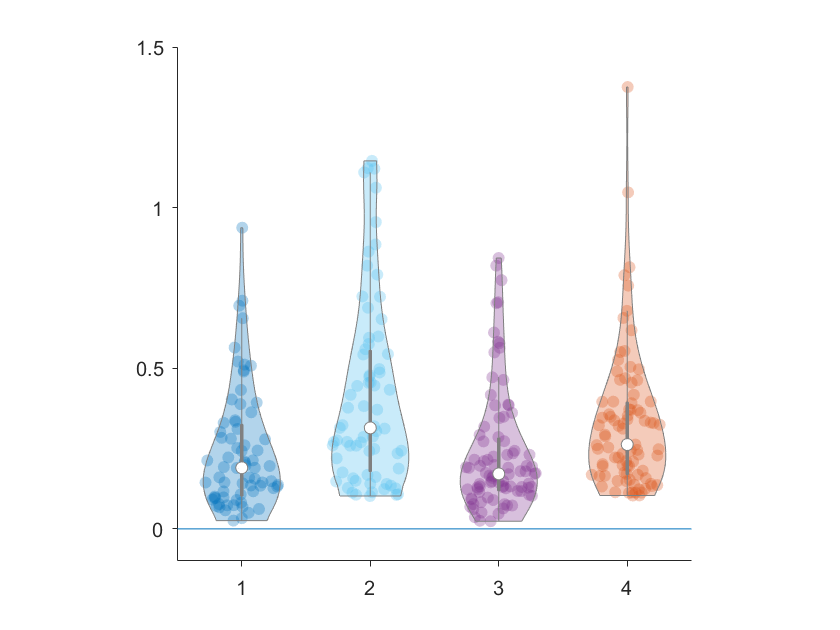


x = [P21nmda_b P21ampa_b P21nmda_o P21ampa_o]';
g = [ones(size(P21nmda_b)) 2*ones(size(P21ampa_b)) 3*ones(size(P21nmda_o)) 4*ones(size(P21ampa_o))]';
 
figure, violinplot(x, g,'bandwidth',.1);
ylim([-0.1 1.5])
xlim([0.5 4.5])
set(gca,'TickDir','out'), box off
axis square

line([0.5 4.5],[0,0])

% ylim([-0.1 .5])
% xlim([0.5 4.5])
% beeswarm(g,x,'sort_style','rand','dot_size',1.1,'MarkerFaceAlpha',1,'use_current_axes',true);
% hold on,
% boxplot(x,g)
% ylim([-0.1 1.5])
% xlim([0.5 4.5])



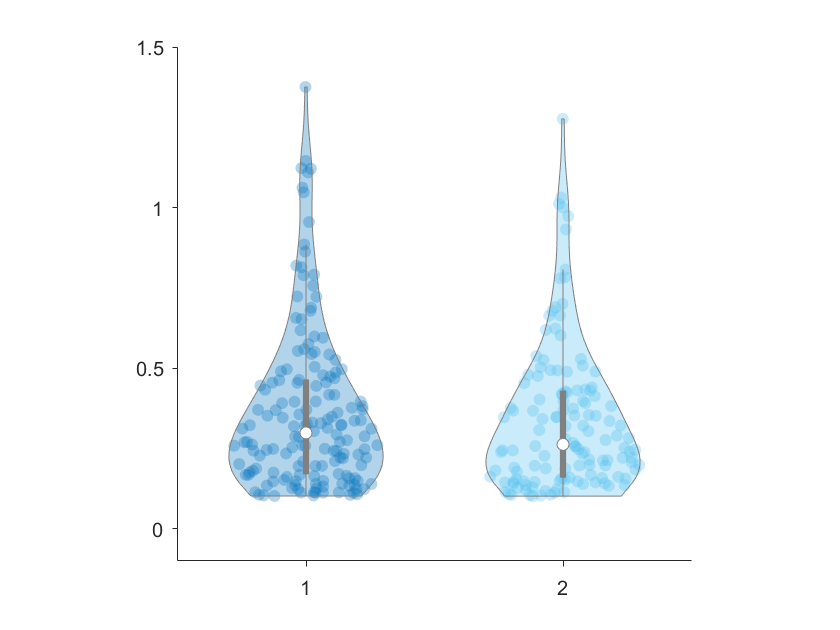


x = [[P21ampa_b P21ampa_o] [ampa_b ampa_o]]';
g = [ones(size([P21ampa_b P21ampa_o])) 2*ones(size([ampa_b ampa_o]))]';
clf

figure, violinplot(x, g,'bandwidth',.1);
ylim([-0.1 1.5])
xlim([0.5 2.5])
set(gca,'TickDir','out'), box off
axis square

% figure, 
% ylim([-0.1 .5])
% xlim([0.5 2.5])
% beeswarm(g,x,'sort_style','rand','dot_size',1.1,'MarkerFaceAlpha',1,'use_current_axes',true);
% hold on,
% boxplot(x,g)
% ylim([-0.1 1.5])
% xlim([0.5 2.5])
% set(gca,'TickDir','out'), box off
% axis square


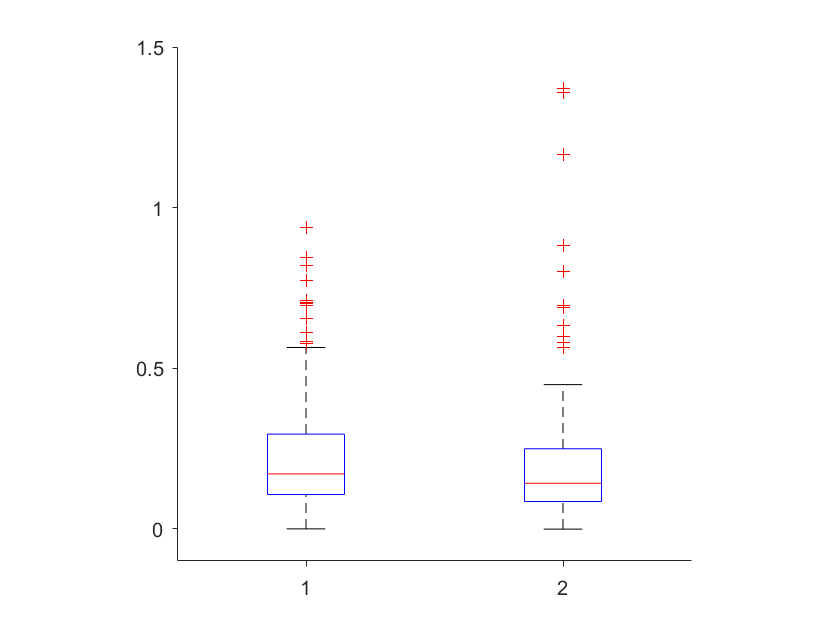

x = [[P21nmda_b P21nmda_o] [nmda_b nmda_o]]';
g = [ones(size([P21nmda_b P21nmda_o])) 2*ones(size([nmda_b nmda_o]))]';
clf
figure, 
ylim([-0.1 .5])
xlim([0.5 2.5])
beeswarm(g,x,'sort_style','rand','dot_size',1.1,'MarkerFaceAlpha',1,'use_current_axes',true);
hold on,
boxplot(x,g)
ylim([-0.1 1.5])
xlim([0.5 2.5])
set(gca,'TickDir','out'), box off
axis square